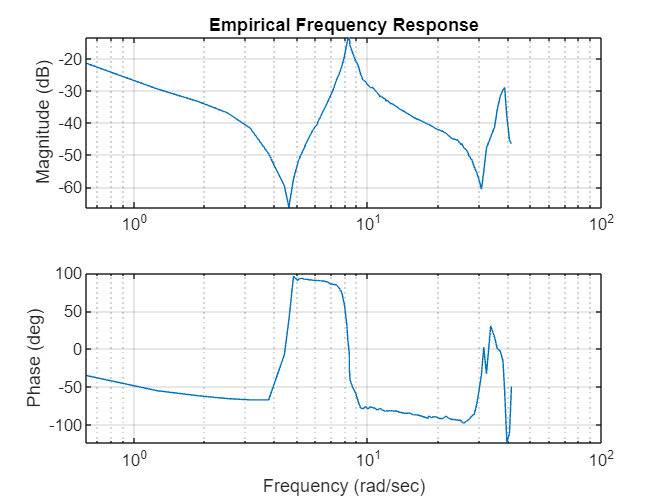

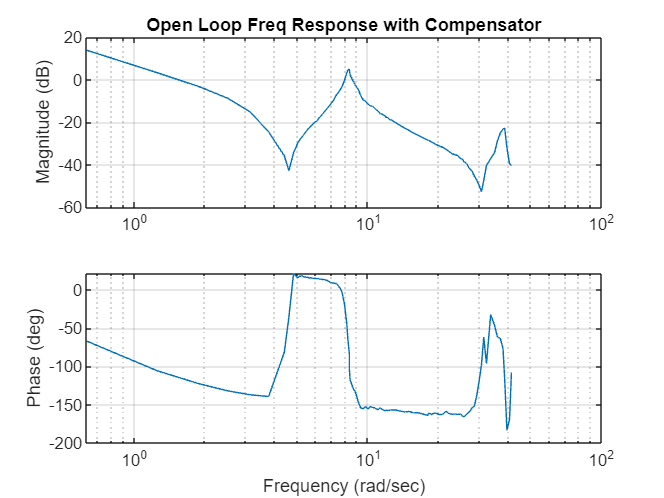

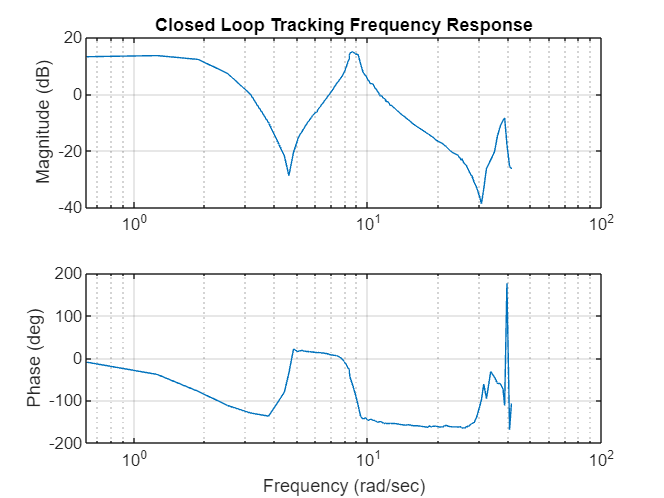

Approximate Gain Crossover at 3.14 rad/s → PM ≈ 50.78 deg


Approx Phase Crossover at 40.48 rad/s → GM ≈ 25.53 dB


Closed-Loop Bandwidth ≈ 3.77 rad/s (0.60 Hz)


% Designing the compensator for the empirical data

% Read Data from Excel
rawTable = readtable('Spacecraft_spin_module_frequency_response_data.xlsx','Sheet','Sheet1');


% Freq in Hz
freq_data_Hz = rawTable.Frequency_Hz_;
% Freq in rad/sec
freq_data_rad_sec = 2*pi*freq_data_Hz;

% Mag in (rad/sec)/V
mag_data_linear = rawTable.Magnitude__rad_sec__V_;
% Mag in dB
mag_data_dB = 20*log10(mag_data_linear);

% Phase in rad
phase_data_rad = rawTable.Phase_rad_;
% Phase in deg
phase_data_deg = phase_data_rad*360/(2*pi);

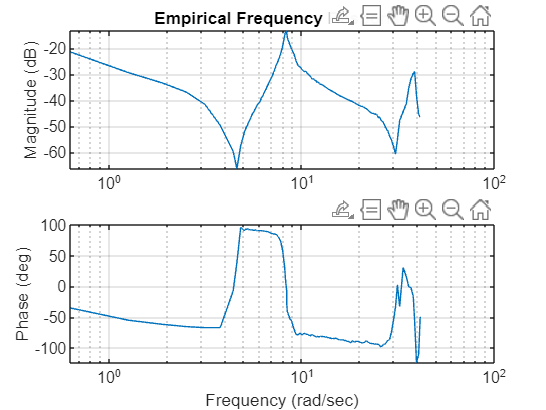

% Converting the empirical data to complex frequency response
H_empirical = mag_data_linear .* exp(1j * phase_data_rad);

% Empirical Bode Plot
figure;
subplot(2,1,1)
semilogx(freq_data_rad_sec, mag_data_dB)
ylabel('Magnitude (dB)')
title('Empirical Frequency Response')
grid on

subplot(2,1,2)
semilogx(freq_data_rad_sec, phase_data_deg)
xlabel('Frequency (rad/sec)')
ylabel('Phase (deg)')
grid on

% Desigining the compensator for empirical data
% We will choose the same compensator as designed for
% the analytic transfer function as the initial compensator
% for the empirical data and then tune as required.

% Lag Compensator
s = tf('s');
w_c = 2*pi*1; % crossover frequency at 1 Hz

% Compensator Design
% Lag compensator (z > p)
% Lag compensator reduces the phase in this frequency range:
% w_start = 0.1*p to w_end = 10*z.
% Also, max phase lag occurs at: w = sqrt(z*p).

C1_lag_empirical = (s+70)/(s+1);
[mag_lag_empirical, phase_lag_empirical, ~] = bode(C1_lag_empirical, freq_data_rad_sec);
mag_lag_empirical = squeeze(mag_lag_empirical);
phase_lag_empirical = squeeze(phase_lag_empirical);

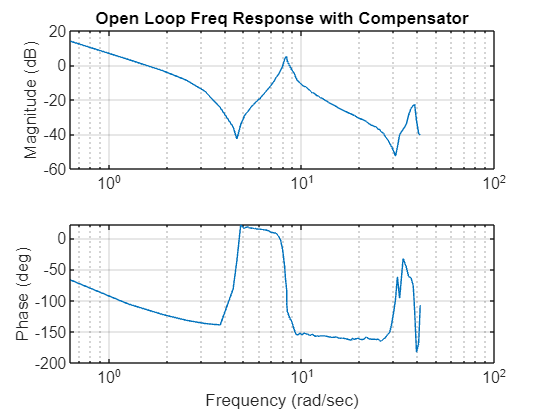

% Open Loop Frequency Response with Compensator
mag_L_empirical = mag_lag_empirical .* mag_data_linear;
mag_L_empirical_dB = 20*log10(mag_L_empirical);
phase_L_empirical_deg = phase_lag_empirical + phase_data_deg;
L_empirical = mag_L_empirical .* exp(1j * deg2rad(phase_L_empirical_deg));

% Plot the bode plot for the open loop frequency response
subplot(2,1,1)
semilogx(freq_data_rad_sec, mag_L_empirical_dB);
%hold on;
%yline(0, 'r--', '0 dB line');
ylabel('Magnitude (dB)')
title('Open Loop Freq Response with Compensator')
grid on

subplot(2,1,2)
semilogx(freq_data_rad_sec, phase_L_empirical_deg);
%hold on;
%yline(-180, 'r--', '-180 deg line')
xlabel('Frequency (rad/sec)')
ylabel('Phase (deg)')
grid on

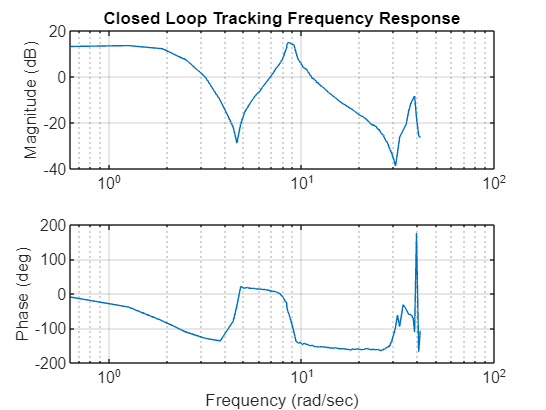

% Unity Feedback Closed Loop system
T_empirical = L_empirical ./ (1 + L_empirical);
K_new_empirical = 5;
T_empirical_total = K_new_empirical .* T_empirical;
mag_T_empirical_total = 20*log10(abs(T_empirical_total));
phase_T_empirical_total = rad2deg(angle(T_empirical_total));

% Plot the closed loop empirical frequency response
subplot(2,1,1)
semilogx(freq_data_rad_sec, 20*log10(abs(T_empirical_total)))
ylabel('Magnitude (dB)')
title('Closed Loop Tracking Frequency Response')
grid on
subplot(2,1,2)
semilogx(freq_data_rad_sec, rad2deg(angle(T_empirical_total)))
xlabel('Frequency (rad/sec)')
ylabel('Phase (deg)')
grid on

% Find the Gain Margin and Phase Margin for the closed loop response
% from the above plots

% Find index of point closest to 0 dB
[~, idx_gc] = min(abs(mag_L_empirical_dB));  % smallest difference from 0 dB
% Estimate phase margin
phase_at_gc = phase_L_empirical_deg(idx_gc);
PM = phase_at_gc + 180;
w_gc = freq_data_rad_sec(idx_gc);
fprintf('Approximate Gain Crossover at %.2f rad/s → PM ≈ %.2f deg\n', w_gc, PM);

Approximate Gain Crossover at 8.64 rad/s → PM ≈ 52.27 deg



% Find index of point closest to -180 deg
[~, idx_pc] = min(abs(phase_L_empirical_deg + 180));  % phase closest to -180 deg
% Estimate gain margin
mag_at_pc = mag_L_empirical_dB(idx_pc);
GM = -mag_at_pc;
w_pc = freq_data_rad_sec(idx_pc);
fprintf('Approx Phase Crossover at %.2f rad/s → GM ≈ %.2f dB\n', w_pc, GM);

Approx Phase Crossover at 39.43 rad/s → GM ≈ 31.98 dB



% Find the bandwidth of the open loop
idx_bw = find(mag_T_empirical_total < -3, 1);
bw_closed_loop = freq_data_rad_sec(idx_bw);
fprintf('Closed-Loop Bandwidth ≈ %.2f rad/s (%.2f Hz)\n', bw_closed_loop, bw_closed_loop/(2*pi));

Closed-Loop Bandwidth ≈ 3.77 rad/s (0.60 Hz)



% We can see from the output that the PM for the closed-loop system
% is 50.78 deg (> 40 deg), the GM is 25.53 dB (> 10 dB) and the
% Bandwidth is 0.60 Hz (~ 1 Hz). All these values are close to what
% was achieved using the analytic transfer function, although we could
% achieve the same performance with one less lag compensator.